clear all;
close all;

% Read images
waldo = imread('where_is_waldo.jpg');
template1 = imread('template1.png');
template2 = imread('template2.png');

% Convert images to grayscale
waldo_gray = rgb2gray(waldo);
template1_gray = rgb2gray(template1);
template2_gray = rgb2gray(template2);

% Initialize the minimum distance and the corresponding coordinates
min_ssd1 = Inf;
min_ssd2 = Inf;
min_x1 = 0;
min_y1 = 0;
min_x2 = 0;
min_y2 = 0;

% Scroll through all the pixels of the reference image
for i = 1:size(waldo_gray, 1) - size(template1_gray, 1)
    for j = 1:size(waldo_gray, 2) - size(template1_gray, 2)
        % Extract a local patch from the image
        patch = double(waldo_gray(i:i+size(template1_gray, 1)-1, j:j+size(template1_gray, 2)-1));
        
        % Calculate the SSD distance between the patch and the template
        ssd1 = sum(sum((patch - double(template1_gray)).^2));
        ssd2 = sum(sum((patch - double(template2_gray)).^2));
        
        % Upload the minimum distance and the corresponding coordinates
        if ssd1 < min_ssd1
            min_ssd1 = ssd1;
            min_x1 = j;
            min_y1 = i;
        end
        
        if ssd2 < min_ssd2
            min_ssd2 = ssd2;
            min_x2 = j;
            min_y2 = i;
        end
    end
end

% Print the minimum SSD distance for both template
disp(['Minimum SSD distance for template 1: ' num2str(min_ssd1)]);

Minimum SSD distance for template 1: 0


disp(['Minimum SSD distance for template 2: ' num2str(min_ssd2)]);

Minimum SSD distance for template 2: 293546


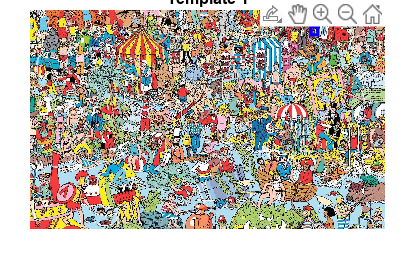


% Display the location of Waldo in the original image for both template
figure;
imshow(waldo);
hold on;
rectangle('Position', [min_x1, min_y1, size(template1_gray, 2), size(template1_gray, 1)], 'EdgeColor', 'b', 'LineWidth', 2);
title('Template 1');

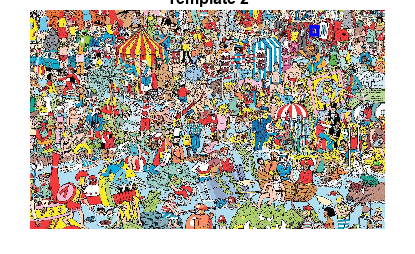


figure;
imshow(waldo);
hold on;
rectangle('Position', [min_x2, min_y2, size(template2_gray, 2), size(template2_gray, 1)], 'EdgeColor', 'b', 'LineWidth', 2);
title('Template 2');